clear, clc, close all
delete(instrfind)

## GET User Inputs & Setup Options

SETUP_VIA_GUI = 1;
ANTENNA_TYPE = 1; %Hardcoded b/c only ISK/BOOST style currently supported.
if(SETUP_VIA_GUI)
    hApp = setup_as(); %use _exported for 2017a support; setup_as() for 2019+
    
else 
    % Manual/programmatic entry
    REAL_TIME_MODE = 0; %1 for from device 0 for playback from dat file
    ENABLE_RECORD = 0;
    datFile.path = '';
    datFile.name = 'areascanner_demo_uart_stream.txt';
    cfgFile.path = '';
    cfgFile.name = 'area_scanner_static_tracker.cfg';
    logFile.path = '';
    logFile.name = 'areascanner_demo_uart_stream.txt';
    offset.height = 2;
    offset.el = 0;
    comPort.cfg = 19;
    comPort.data = 20;
    comPort.status = 0;
    zones.enable = 1;
    zones.criticalStart = 0;
    zones.criticalEnd = 1;
    zones.warnStart = 1;
    zones.warnEnd = 4;
    zones.projTime = 2;
end

offset.az = 0; % TODO need to add back azimuth offset for user input

## Set up file to record

if(ENABLE_RECORD && REAL_TIME_MODE)
    
    if(~isempty(logFile.path))
        % append slash if needed
        if(logFile.path(end)~='\' && logFile.path(end)~='/')
            logFile.path(end+1) = '\';
        end
        status = mkdir(logFile.path);
    else
        status = 1;
    end
    if(status)
        fid = fopen([logFile.path logFile.name],'w+');
    end
    if fid~= -1
        fprintf(['Opening ' logFile.name '. Ready to log data. \n']);
    else
        fprintf('Error with log file name or path. No logging. \n');
        ENABLE_RECORD = 0;
    end
else
    fid = -1;
    ENABLE_RECORD = 0;
end

## SET and PARSE CFG FILE

try 
    [cliCfg] = readCfgFile([cfgFile.path cfgFile.name]);
catch ME
    fprintf('Error: Could not open CFG file. Quitting.');
    if(ENABLE_RECORD)
        fclose(fid);
    end
    return;
end

Opening configuration file 



%Define supported CLI commands
sdkVersion = '03.03.00.01'; %TODO read this from device
demoType = 'AS';
[supported_cfgs] = defineCLICommands(sdkVersion,demoType);
    
%Parse CLI strings and calculate derived parameters
P = parseCLICommands2Struct(cliCfg, supported_cfgs);

Parsing configuration file...


calc_P = calculateChirpParams(P);

## INIT SERIAL PORTS

if(REAL_TIME_MODE)
    %Init Ports
    hDataPort = initDataPort(comPort.data);
    hCfgPort = initCfgPort(comPort.cfg);
    
    %Check Port Status
    if(comPort.status == 0) %Unknown status
        if(hCfgPort ~= -1 && hDataPort ~=-1)
            if(hDataPort.BytesAvailable)
                %TODO: remove warning when config reload w/o NRST is enabled
                comPort.status = -1;
                fprintf('Device appears to already be running. Will not be able to load a new configuration. To load a new config, press NRST on the EVM and try again.');    
            else       
                fprintf(hCfgPort, 'version');
                pause(0.5); % adding some delay to make sure bytes are received
                response = '';
                if(hCfgPort.BytesAvailable)
                    for i=1:10 % version command reports back 10 lines TODO: change if SDK changes response
                        rstr = fgets(hCfgPort);
                        response = join(response, rstr);
                    end
                    fprintf('Test successful: CFG Port Opened & Data Received');
                    comPort.status = 1;
                else
                    fprintf('Port opened but no response received. Check port # and SOP mode on EVM');
                    comPort.status = -2;
                    fclose(hDataPort);
                    fclose(hCfgPort);
                end
            end
        else
            comPort.status = -2;
            fprintf('Could not open ports. Check port # and that EVM is powered with correct SOP mode.');    
        end
    end
     
else %REPLAY MODE
    
    %Load Data file
end

## Set flags based on COM port status

global RUN_VIZ
if(~REAL_TIME_MODE)
    RUN_VIZ = 1;
    LOAD_CFG = 0;
elseif(comPort.status == 1)
    LOAD_CFG = 1;
    RUN_VIZ = 1;
elseif(comPort.status == -1)
    LOAD_CFG = 0;
    RUN_VIZ = 1;
else
    RUN_VIZ = 0;
    LOAD_CFG = 0;
end

## Load Config

if(LOAD_CFG) 
    loadCfg(hCfgPort, cliCfg);
end
        
if(RUN_VIZ)

## INIT Figure

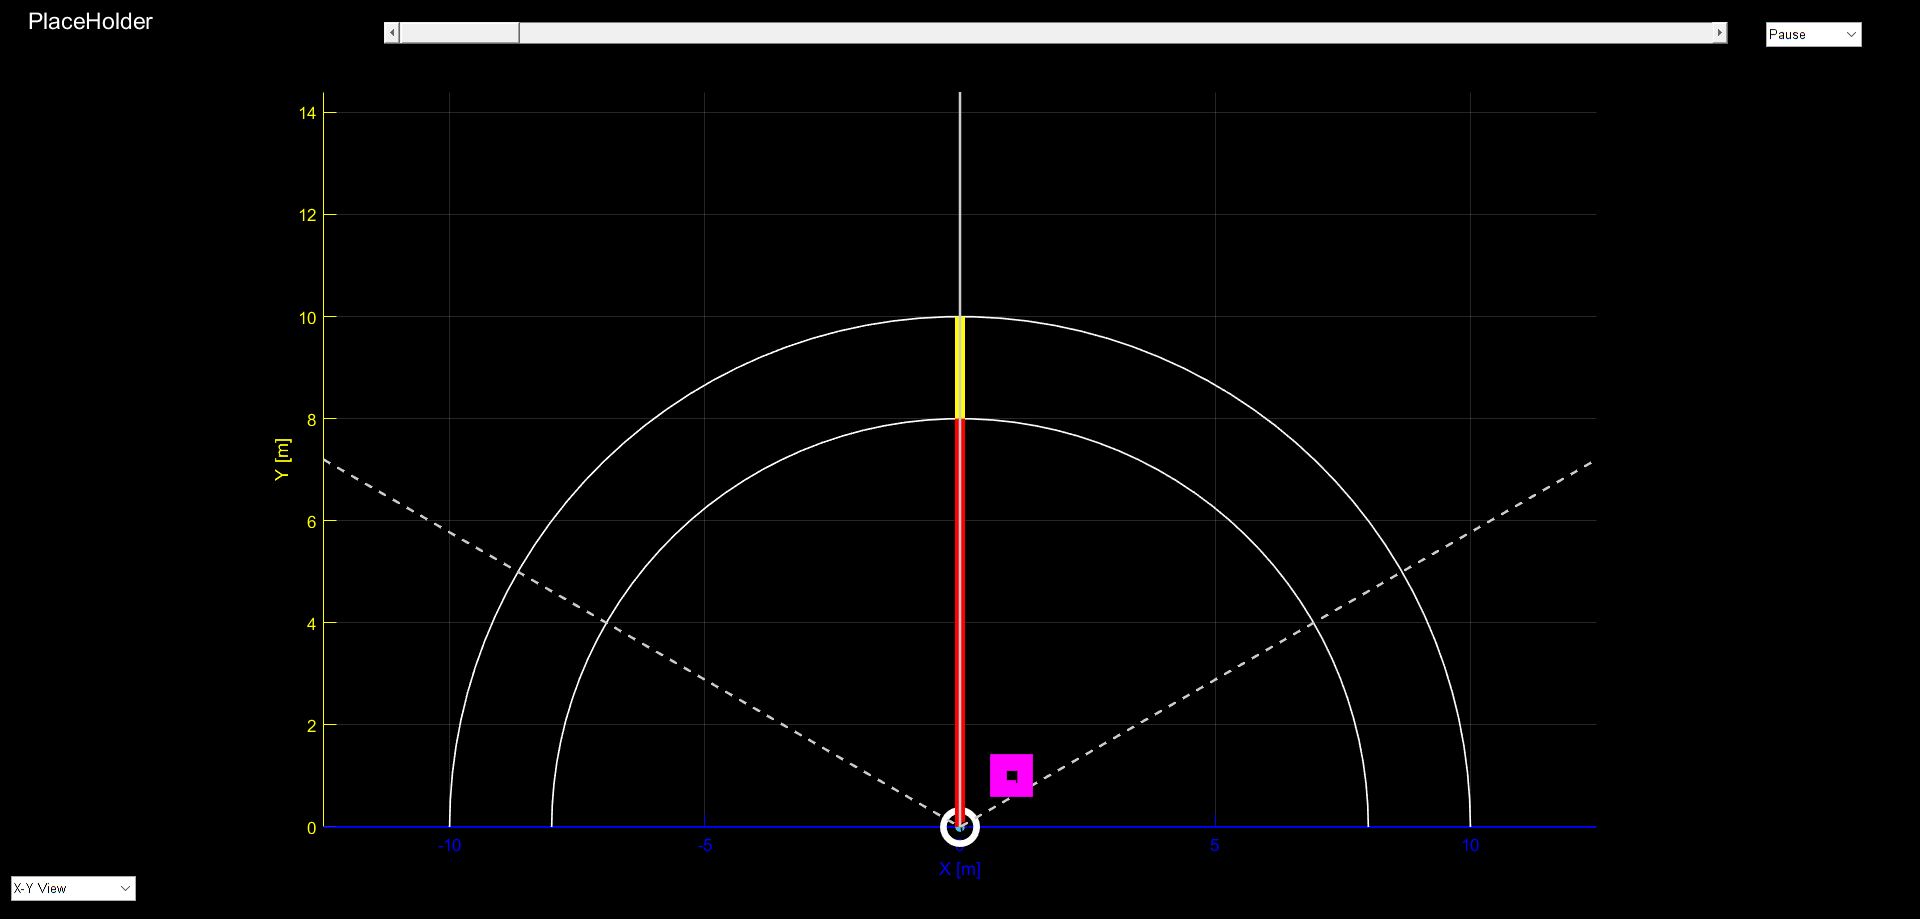

SHOW_DYNAMIC_PT_CLOUD = 1;
SHOW_STATIC_PT_CLOUD = 1;
SHOW_TRACKED_OBJ = 1;
SHOW_STATS = 1;
SHOW_ZONE = zones.enable;

hFig = figure('Name', 'Area Scanner Visualizer V2.0.0','Color','black','CloseRequestFcn',@plotfig_closereq);

% init plot axes
maxRange = max([calc_P.rangeMax_m]);
[hFig, hAx3D] = init3DPlot_AS(hFig,[-maxRange maxRange],[0 maxRange], [0 offset.height]);

% init fov lines - approximate guidelines only
if (ANTENNA_TYPE==1)
    azFOV = 120; 
    elFOV = 40;  
else
    azFOV = 160; 
    elFOV = 160;
end
hFOVLines = drawFOVLines(hAx3D, azFOV, elFOV, maxRange, offset);
%reset the axes limits based on FOV TODO: Allow UI for axis limits
hAx3D.XLim = [min(hFOVLines.azimuth.XData) max(hFOVLines.azimuth.XData)];
hAx3D.YLim = [0 max([hFOVLines.boresight.YData hFOVLines.azimuth.YData hFOVLines.elevation.YData])];
hAx3D.ZLim = [0 max([hFOVLines.boresight.ZData hFOVLines.azimuth.ZData hFOVLines.elevation.ZData])];

% init handle for visualizing dynamic pt cloud
styleDynPtCloud = {'LineStyle','none','Marker','.','Color',[0.3010 0.7450 0.9330],'MarkerSize',20};
hDynamicPtCloud = line(hAx3D,0,0,0, styleDynPtCloud{:});

% init handle for visualizing static pt cloud
styleStaticPtCloud = {'LineStyle','none','Marker','square','Color','m','MarkerSize',20,'LineWidth',10};
hStaticPtCloud = line(hAx3D,1,1,1, styleStaticPtCloud{:});

% init handle for visualizing tracked objects
styleTrackObj = {'LineStyle','none','Marker','o','MarkerEdge','w','MarkerSize',20,'LineWidth',4};
hTrackObj = line(hAx3D,0,0,0, styleTrackObj{:});
hTrackObjLabel = text([0 1],[0 1],[0 1],{'0', '1'},'FontSize',10);
% show projection lines
hProjection = line(hAx3D,1,1,1);

% init handle for visualizing AS zones
if(SHOW_ZONE)
    rangeCritStart = zones.criticalStart;
    rangeCritEnd = zones.criticalEnd;
    rangeWarnStart = zones.warnStart;
    rangeWarnEnd = zones.warnEnd;

    zoneCrit = initRadialZone(rangeCritStart,rangeCritEnd,0,0,0,[1 0 0]);
    zoneCrit.Parent = hAx3D;
    zoneCrit.FaceAlpha = 0;

    zoneWarn = initRadialZone(rangeWarnStart,rangeWarnEnd,0,0,0,[1 1 0]);
    zoneWarn.Parent = hAx3D;
    zoneWarn.FaceAlpha = 0;
    
    % draw lines for zone indicator in YZ view
    hLineWarn = line(hAx3D,[0 0],[rangeWarnStart rangeWarnEnd],[0 0], 'LineStyle', '-', 'Color','y','LineWidth',6);
    hLineCrit = line(hAx3D,[0 0],[rangeCritStart rangeCritEnd],[0 0], 'LineStyle', '-', 'Color','r','LineWidth',6);
     
end

% init handle for stats textbox
styleStats = {'LineStyle','none', 'FontUnits','normalized','FontSize',0.025};
statsString = {'PlaceHolder'};
hStats = annotation(hFig,'textbox',[0.01 0.8 0.3 0.2], 'String', statsString, styleStats{:},'Color','w'); 

% init uicontrols
selectView = uicontrol(hFig,'Style','popupmenu',...
    'Position',[10 10 100 25],...
    'String',{'X-Y View','Y-Z View','X-Z View','3D View'},...
    'Callback',@(selectView,event) selection(selectView,hAx3D));

if(~REAL_TIME_MODE)
    hFrameSlider = uicontrol(hFig,'Style','slider',...
    'Min',1,'Max',100,'Value',1,...
    'Units','Normalized', 'Position',[0.2 0.95 0.7 0.025]);
    hFrameSlider.SliderStep = [1 10].*(1/(hFrameSlider.Max-hFrameSlider.Min));
    
    hPlayControl = uicontrol(hFig,'Style','popupmenu',...
    'Units','Normalized', 'Position',[0.92 0.95 0.05 0.025],...
    'String', {'Pause','Play'});
end

## Pre-compute transformation matrix

rotMat_el = [1 0 0; 0 cosd(offset.el) -sind(offset.el); 0 sind(offset.el) cosd(offset.el)];
transMat = rotMat_el;

## main - parse UART and update plots

if(REAL_TIME_MODE)
    bytesBuffer = zeros(1,hDataPort.InputBufferSize);
    bytesBufferLen = 0;
    isBufferFull = 0;
    READ_MODE = 'FIFO';
else
    % read in entire file 
    [bytesBuffer, bytesBufferLen, bytesAvailableFlag] = readDATFile2Buffer([datFile.path datFile.name], 'hex_dat');
    READ_MODE = 'FIFO';
    [allFrames, bytesBuffer, bytesBufferLen, numFramesAvailable,validFrame] = parseBytes_AS(bytesBuffer, bytesBufferLen, 'FIFO');
    hFrameSlider.Max = numFramesAvailable;
    hFrameSlider.SliderStep = [1 10].*1/(hFrameSlider.Max-hFrameSlider.Min);
end

while (RUN_VIZ)    
    
    % get bytes from UART buffer or DATA file
    if(REAL_TIME_MODE)
        [bytesBuffer, bytesBufferLen, isBufferFull, bytesAvailableFlag] = readUARTtoBuffer(hDataPort, bytesBuffer, bytesBufferLen, ENABLE_RECORD, fid);
         % parse bytes to frame
        [newframe, bytesBuffer, bytesBufferLen, numFramesAvailable,validFrame] = parseBytes_AS(bytesBuffer, bytesBufferLen, READ_MODE);
        frameIndex = 1;
    else
%         frameIndex = round(hFrameSlider.Value);
%         newframe = allFrames(frameIndex);
        [newframe, bytesBuffer, bytesBufferLen, numFramesAvailable,validFrame] = parseBytes_AS(bytesBuffer, bytesBufferLen, READ_MODE);
        frameIndex = 1;
    end
    
   
    
    if(validFrame(frameIndex))
        statsString = {['Frame: ' num2str(newframe.header.frameNumber)], ['Num Frames in Buffer: ' num2str(numFramesAvailable)]}; %reinit stats string each new frame
        if(1)

            % set frame flags
            HAVE_VALID_DYNAMIC_PT_CLOUD = newframe.header.numDetectedObj ~= 0 && ~isempty(newframe.detObj);
            HAVE_VALID_STATIC_PT_CLOUD = newframe.header.numStaticDetectedObj ~= 0 && ~isempty(newframe.staticDetObj);
            HAVE_VALID_TARGET_LIST = ~isempty(newframe.targets);
            
            if(SHOW_DYNAMIC_PT_CLOUD)            
                if(HAVE_VALID_DYNAMIC_PT_CLOUD)
                    % Pt cloud hasn't been transformed based on offset TODO: move transformation to device
                    rotatedPtCloud = transMat * [newframe.detObj.x; newframe.detObj.y; newframe.detObj.z];
                    hDynamicPtCloud.XData = rotatedPtCloud(1,:);
                    hDynamicPtCloud.YData = rotatedPtCloud(2,:);
                    hDynamicPtCloud.ZData = rotatedPtCloud(3,:)+offset.height; 

                else
                    hDynamicPtCloud.XData = [];
                    hDynamicPtCloud.YData = [];
                    hDynamicPtCloud.ZData = [];
                end
            end
            
            if(SHOW_STATIC_PT_CLOUD)            
                if(HAVE_VALID_STATIC_PT_CLOUD)
                    % Pt cloud hasn't been transformed based on offset TODO: move transformation to device
                    rotatedPtCloud = transMat * [newframe.staticDetObj.x'; newframe.staticDetObj.y'; newframe.staticDetObj.z'];
                    hStaticPtCloud.XData = rotatedPtCloud(1,:);
                    hStaticPtCloud.YData = rotatedPtCloud(2,:);
                    hStaticPtCloud.ZData = rotatedPtCloud(3,:)+offset.height; 

                else
                    hStaticPtCloud.XData = [];
                    hStaticPtCloud.YData = [];
                    hStaticPtCloud.ZData = [];
                end
            end

            if(SHOW_TRACKED_OBJ)
                if(HAVE_VALID_TARGET_LIST)
                    numTargets = numel(newframe.targets.tid);
                    if(numTargets > 0)
                        %Tracker coordinates have been transformed by
                        %azimuth rotation but not elevation.
                        %TODO: Add elevation rotation and height
                        %offset on device
                        rotatedTargets = rotMat_el * [newframe.targets.posX; newframe.targets.posY; newframe.targets.posZ;];
                        hTrackObj.XData = rotatedTargets(1,:);
                        hTrackObj.YData = rotatedTargets(2,:);
                        hTrackObj.ZData = rotatedTargets(3,:)+offset.height;
                        delete(hTrackObjLabel);
                        hTrackObjLabel = text(hAx3D,hTrackObj.XData,hTrackObj.YData,...
                            hTrackObj.ZData ,arrayfun(@(x) {num2str(x)}, newframe.targets.tid),...
                            'FontSize',10,'HorizontalAlignment','center','VerticalAlignment','middle','Color','w');
                        
                    else
                        delete(hTrackObjLabel);
                        hTrackObjLabel = [];
                        hTrackObj.XData = [];
                        hTrackObj.YData = [];
                        hTrackObj.ZData = [];  
                    end
                else
                        delete(hTrackObjLabel);
                        hTrackObjLabel = [];
                        hTrackObj.XData = [];
                        hTrackObj.YData = [];
                        hTrackObj.ZData = [];  
                end
            end

            if(SHOW_ZONE) %TO DO: OPTIMIZE VISUALIZATION
                
               if(HAVE_VALID_DYNAMIC_PT_CLOUD)
                rangeDynamicPts = sqrt(hDynamicPtCloud.XData.^2+ hDynamicPtCloud.YData.^2);
                dynamicPtsInCriticalZone = (rangeDynamicPts  >= rangeCritStart) & (rangeDynamicPts  <= rangeCritEnd);
               else
                dynamicPtsInCriticalZone = 0;   
               end
               
               if(HAVE_VALID_STATIC_PT_CLOUD)
                rangeStaticPts = sqrt(hStaticPtCloud.XData.^2+ hStaticPtCloud.YData.^2);
                staticPtsInCriticalZone = (rangeStaticPts >= rangeCritStart) & (rangeStaticPts <= rangeCritEnd);
               else
                staticPtsInCriticalZone = 0;   
               end
               
               if(HAVE_VALID_TARGET_LIST)
                targetPos = [newframe.targets.posX; newframe.targets.posY; newframe.targets.posZ;];
                targetVel = [newframe.targets.velX; newframe.targets.velY;  newframe.targets.velZ]; %TODO: Smooth out instantaneous vel
                targetProjLocation = targetPos+targetVel.*zones.projTime;
                rotTargetOrigin = rotMat_el*targetPos+ [0;0;offset.height];
                rangeOrigin = sqrt(rotTargetOrigin(1,:).^2 + rotTargetOrigin(2,:).^2);
                rotTargetProjLocation = rotMat_el*targetProjLocation + [0;0;offset.height];
                rangeProjection = sqrt(rotTargetProjLocation(1,:).^2 + rotTargetProjLocation(2,:).^2);
                

                tracksInCriticalZone = (rangeOrigin >= rangeCritStart) & (rangeOrigin <= rangeCritEnd);
                tracksInWarnZone = (rangeOrigin > rangeWarnStart) & (rangeOrigin <= rangeWarnEnd);
                tracksProjectedInWarnZone = (rangeProjection > rangeWarnStart) & (rangeProjection <= rangeWarnEnd); 
                tracksProjectedInCriticalZone = (rangeProjection > rangeCritStart) & (rangeProjection <= rangeCritEnd); 

               else
                tracksInCriticalZone = 0;
                tracksInWarnZone = 0; 
                tracksProjectedInWarnZone = 0;
               end
                        
               % toggle critical zone indicator
               if(nnz(tracksInCriticalZone) || nnz(staticPtsInCriticalZone) ||  nnz(dynamicPtsInCriticalZone))
                   zoneCrit.FaceAlpha = 0.25;
                   hLineCrit.Visible = 'on';
               else
                   zoneCrit.FaceAlpha = 0;
                   hLineCrit.Visible = 'off';
               end
               
               % toggle warn zone indicator
               if(nnz(tracksInWarnZone) || nnz(tracksProjectedInWarnZone))
                   zoneWarn.FaceAlpha = 0.25;
                   hLineWarn.Visible = 'on';
               else
                   zoneWarn.FaceAlpha = 0;
                   hLineWarn.Visible = 'off';
               end
               
               % show projection lines for targets 
               if(HAVE_VALID_TARGET_LIST)
                   delete(hProjection);
                   % draw projection lines for all targets
                   hProjection = line(hAx3D, [rotTargetOrigin(1,:); rotTargetProjLocation(1,:)],...
                       [rotTargetOrigin(2,:); rotTargetProjLocation(2,:)],...
                       [rotTargetOrigin(3,:);rotTargetOrigin(3,:)],...
                       'LineStyle','-','LineWidth',5,'Color','g');
                   if(nnz(tracksProjectedInWarnZone))
                       [hProjection(tracksProjectedInWarnZone).Color] = deal([1 1 0]);
                   end

                   if(nnz(tracksProjectedInCriticalZone))
                       [hProjection(tracksProjectedInCriticalZone).Color] = deal([1 0 0]);
                   end

                   else
                   delete(hProjection);
                   hProjection = [];
               end
            end
            
            if(SHOW_STATS)
               if(HAVE_VALID_DYNAMIC_PT_CLOUD)
                   statsString{end+1} = ['Dynamic Points: ' num2str(newframe.header.numDetectedObj)];
               else
                   statsString{end+1} = ['Dynamic Points: '];
               end
               
               if(HAVE_VALID_STATIC_PT_CLOUD)
                   statsString{end+1} = ['Static Points: ' num2str(newframe.header.numStaticDetectedObj)];
               else
                   statsString{end+1} = ['Static Points: '];
               end
               
               if(HAVE_VALID_TARGET_LIST)
                   statsString{end+1} = ['Num Tracked Obj: ' num2str(numTargets)];
               else
                   statsString{end+1} = ['Num Tracked Obj: '];
               end
               
               hStats.String = statsString;
            end 
            

            
        end % have validFrame
        if(REAL_TIME_MODE)
            drawnow limitrate
        else
            drawnow
            if(RUN_VIZ && hPlayControl.Value == 2 && hFrameSlider.Value+1<=hFrameSlider.Max)
                hFrameSlider.Value = hFrameSlider.Value+1;
            end
        end
    else % have data in newFrame
    end
end %while inf

## close ports

if(REAL_TIME_MODE)
    delete(instrfind);
    if(ENABLE_RECORD)
        c = fclose(fid);
        if(c == 0)
            disp('Log file closed w/o error.')
        else
            disp('Error closing log file.');
        end
    end
    disp('Visualizer terminated.')
end
end

## Helper functions

function plotfig_closereq(src,callbackdata)
global RUN_VIZ
% Close request function 
% to display a question dialog box 
   s = questdlg('Close This Figure?',...
      'Close Request Function',...
      'Yes','No','Yes'); 
   switch s 
      case 'Yes'
         RUN_VIZ = 0; 
         delete(gcf)
      case 'No'
         RUN_VIZ = 1;
      return 
   end
end

function selection(selectView,ax)
    val = selectView.Value;
    switch val
        case 1
            view(ax, 0,90);           
        case 2
            view(ax, 90,0);
        case 3
            view(ax, 0,0);
        case 4
            view(ax, 170,10);
    end
end